% 
clear;
clf;
clc;
% 
c = physconst("Lightspeed");
% freq params
f = 3e9; % 3 GHz
w = 2*pi*f;
lam = freq2wavelen(f);
k = 2*pi/lam;
% array params
xmin = -1.5;xmax = 1.5;
da = lam*0.5;
Na = round((xmax-xmin)/da);
d = lam*1.1;
% d = da*2;
stp = d/lam;
N = round((xmax-xmin)/d);
dx = linspace(xmin,xmax,N)';
dxa = linspace(xmin,xmax,Na)';
%
phi = -20

phi = -20

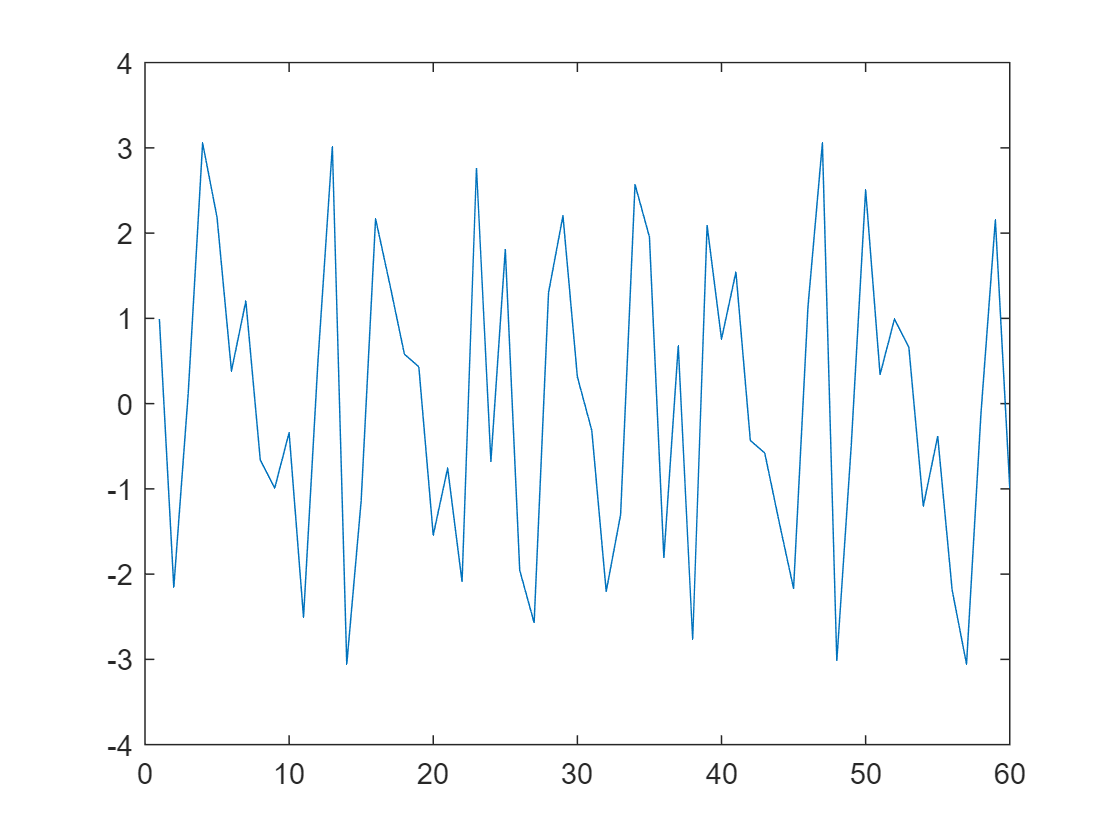

theta = -90:0.5:90;
valuesOk = distribution_former(dxa,f,phi,0);

phsOk = angle(valuesOk);

phsOkd = rad2deg(phsOk);

plot(phsOk)

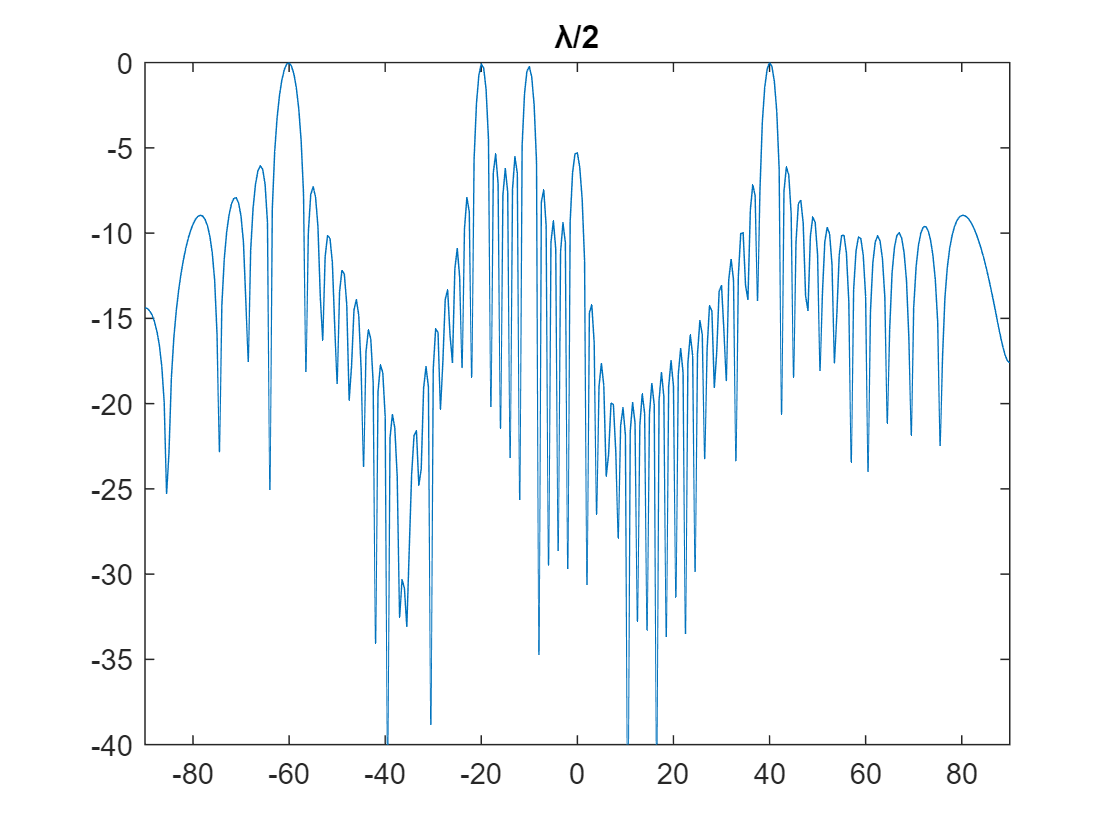


rstOk = aec_simulation(valuesOk, dxa,f,theta);
rstInt = aec_simulation(valuesInt, dxa,f,theta);
rstRare = aec_simulation(valuesRare, dx,f,theta);

rstOkT = pow2db(abs(rstOk));rstOkT = rstOkT - max(rstOkT);
rstIntT = pow2db(abs(rstInt));rstIntT = rstIntT - max(rstIntT);
rstRareT = pow2db(abs(rstRare));rstRareT = rstRareT - max(rstRareT);

plot(theta, rstOkT)
axis([-inf inf -40 0])
title("\lambda/2")

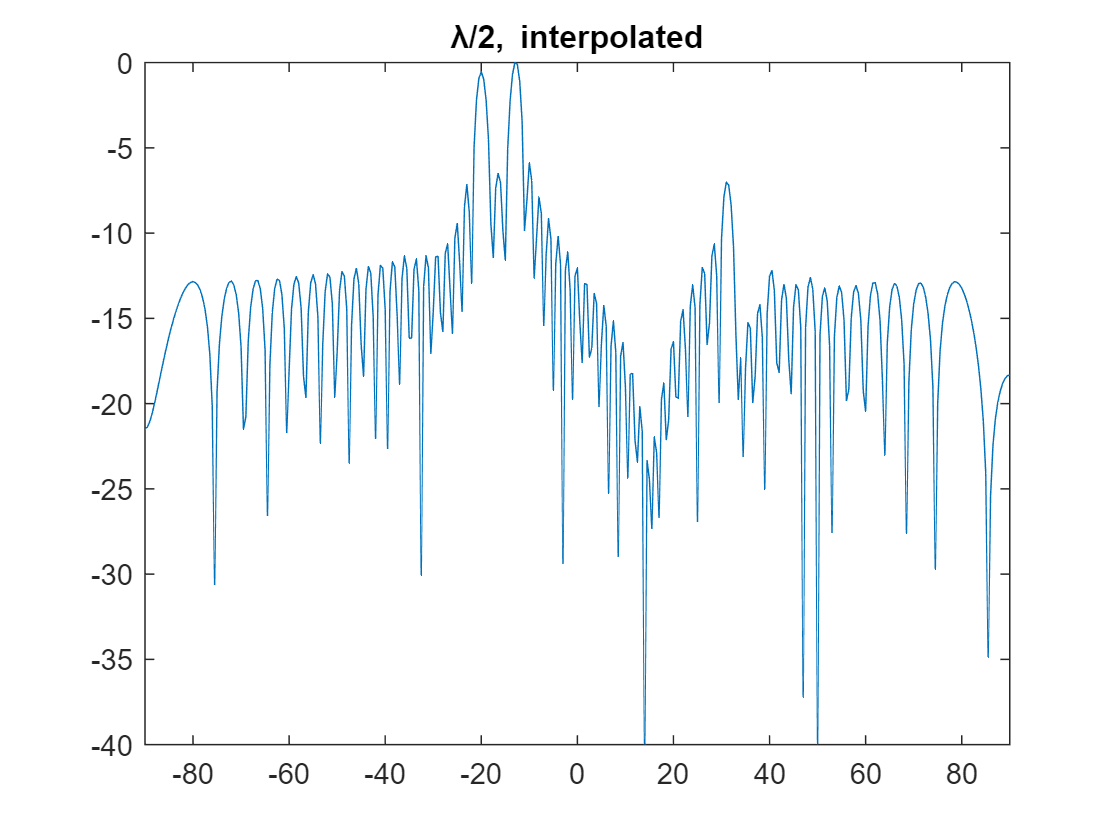


plot(theta, rstIntT)
axis([-inf inf -40 0])
title("\lambda/2, interpolated")

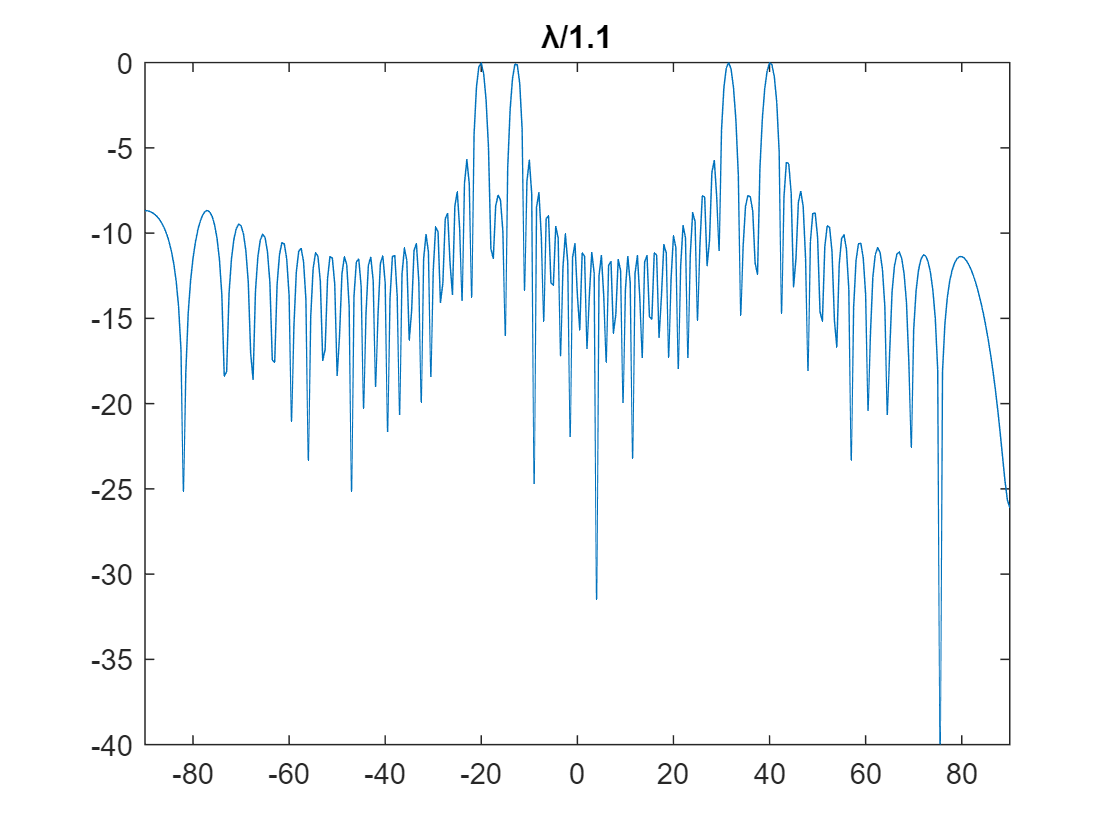


plot(theta, rstRareT)
axis([-inf inf -40 0])
f1 = sprintf("\\lambda/%0.1f",stp);
title(f1)

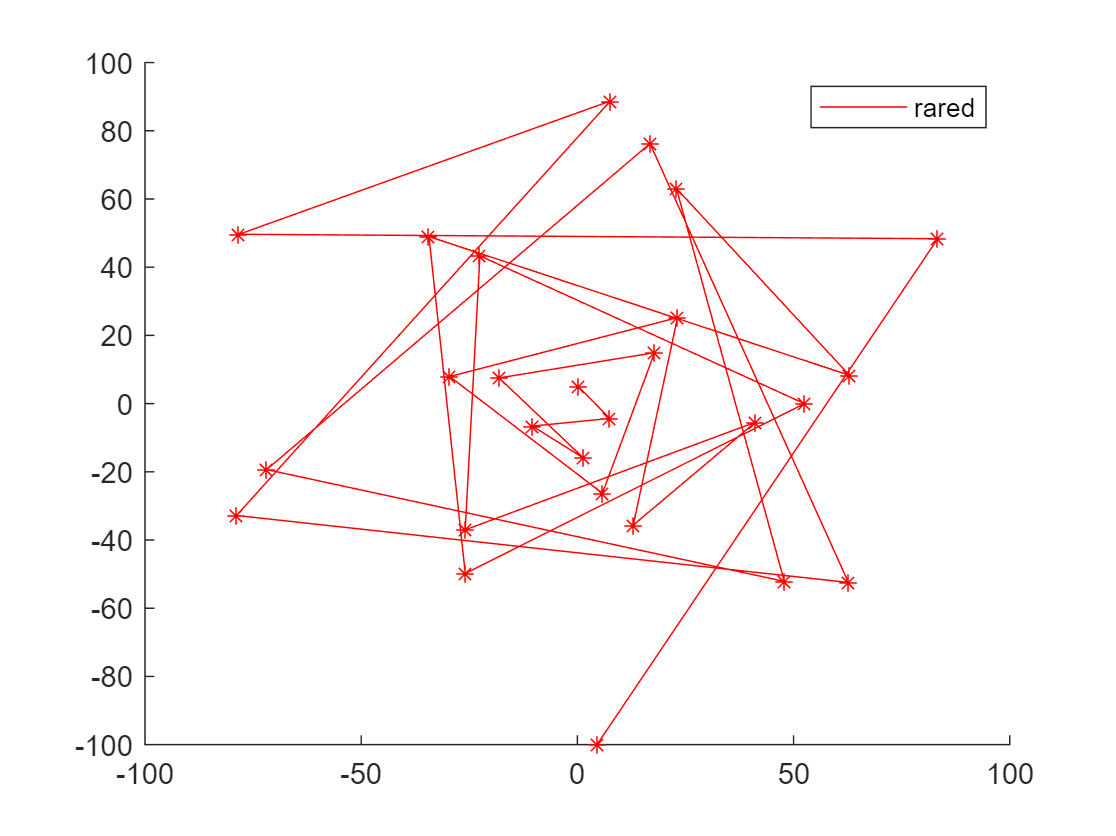


rs = linspace(5,100,length(dxa))';
rsr = linspace(5,100,length(dx))';
vsi = rs.*exp(1i.*phsInt);
vso = rs.*exp(1i.*phsOk);
vsr = rsr.*exp(1i.*phsRare);

figure
hold on
plot(vsr,'r-')
plot(vsr,'r*')
legend("rared")

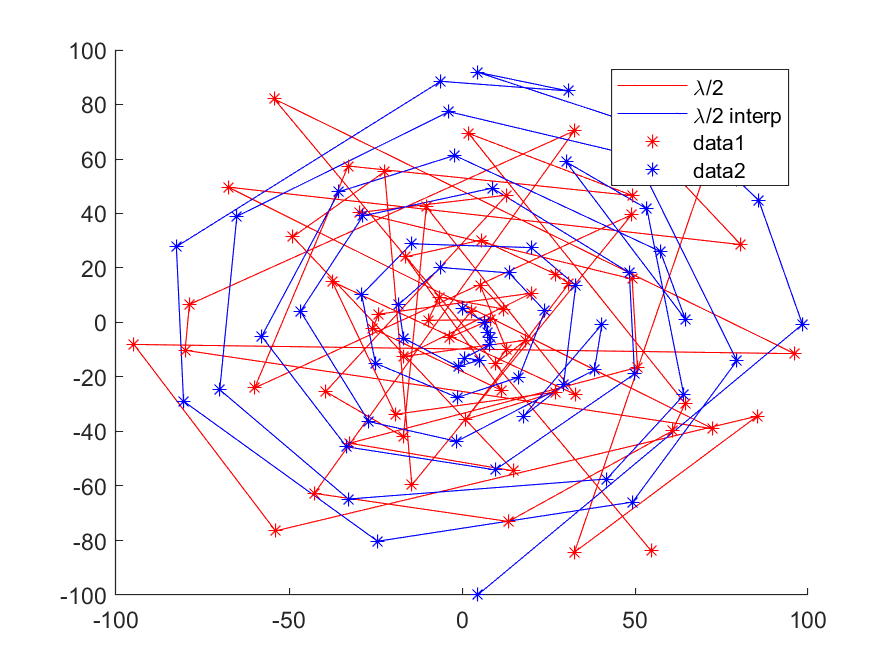


figure
hold on
plot(vso,'r-')
plot(vsi,'b-')
legend(["\lambda/2","\lambda/2 interp"])

plot(vso,'r*')
plot(vsi,'b*')